# PTC3213 - Eletromagnetismo

*Exercício Programa 1 *

*14 de outubro de 2016*

*Alunos:*

*Beatriz de Oliveira - 9350161*

*Daniel Nery Silva de Oliveira - 9349051 *

*Mateus Almeida Barbosa - 9349072*

*Turma 3 - Professor Leb*

Limpa o espaço de trabalho e fecha as figuras abertas

clear;
close all;

## Constantes

Propriedades

epsilon0 = 8.85418782e-12; % permissividade elétrica no vácuo
epsilon = 1.9 * epsilon0;  % permissividade elétrica no meio

sigma  = 3.2e-3; % S/m
sigma1 = 3.0e-3; % S/m para letra (e)

potencial_interno = 100; % Potencial do condutor interno

Dimensoes (m)

a = 11e-2;     
b = 6e-2;      % Leb
c = 3e-2;      % nusp7 = 1
d = b - 3e-2;  % nusp6 = 6
g = 2e-2;      % nusp5 = 0
h = (b-d)/2;

e = 1; % espessura

% Delta para divisão da malha e precisão
delta = 4e-4;

## Conversão do retângulo para grade de pontos

Distâncias convertidas para matriz de pontos

a_matriz = round(a/delta) + 1;
b_matriz = round(b/delta) + 1;
c_matriz = round(c/delta) + 1;
d_matriz = round(d/delta) + 1;
g_matriz = round(g/delta) + 1;
h_matriz = round(h/delta) + 1;

% Outras medidas
gc  = round((g+c)/delta) + 1;
bhd = round((b-h-d)/delta) + 1;
bh  = round((b-h)/delta) + 1;

V = zeros(b_matriz, a_matriz);
V(bhd:bh, g_matriz:gc) = 100;

## Matriz de potenciais

Itera ate a diferenca maxima entre dois pontos consecutivos ser menor que 0.001

diff = 1;
while diff >= 0.001
   diff = 0;
   for l = 2:b_matriz-1
       for c = 2:a_matriz-1
           % Não é necessário computar os pontos dentro do condutor interno
           if V(l,c) ~= 100
               ant = V(l,c);
               V(l,c) = (V(l-1,c) + V(l+1, c) + V(l, c - 1) + V(l, c + 1))/4;
               if (abs(V(l,c) - ant) >= diff)
                   diff = abs(V(l,c) - ant);
               end
           end
       end
   end
end

## Campo Elétrico (Dual)

Matriz para as linhas de campo

E = zeros(size(V));
[l, c] = size(E);
meio = (l+1)/2;

E(meio, 1:g_matriz) = 100; % Lado "A"
E(meio:bh-1, g_matriz+1:gc-1) = NaN; % Interior do quadrado

diff = 1;
while diff > 0.001;
    diff = 0;
    for i = meio+1:l
        for j = 1:c
            if ~isnan(E(i,j))
                ant = E(i,j);
                if j == 1 && i < l
                    E(i,j) = (2*E(i,j+1) + E(i-1,j) + E(i+1,j))/4;
                elseif i < bh && j == g_matriz
                    E(i,j) = (2*E(i,j-1) + E(i-1,j) + E(i+1,j))/4;
                elseif i < bh && j == gc
                    E(i,j) = (2*E(i,j+1) + E(i-1,j) + E(i+1,j))/4;
                elseif i == bh && j > g_matriz && j < gc
                    E(i,j) = (2*E(i+1,j) + E(i, j-1) + E(i, j+1))/4;
                elseif j == c && i < l
                    E(i,j) = (2*E(i,j-1) + E(i-1,j) + E(i+1,j))/4;
                % Borda inferior
                elseif i == l
                    if j == 1
                        E(i,j) = (2*E(i-1,j) + 2*E(i,j+1))/4;
                    elseif j == c
                        E(i,j) = (2*E(i-1,j) + 2*E(i,j-1))/4;
                    else
                        E(i,j) = (2*E(i-1,j) + E(i, j-1) +E(i, j+1))/4;
                    end
                else
                    E(i,j) = (E(i+1,j) +E(i-1,j) + E(i,j+1) + E(i,j-1))/4;
                end
                if (abs(E(i,j) - ant) >= diff)
                   diff = abs(E(i,j) - ant);
                end
            end
        end
    end
end

% Rebate a matriz
E2 = flipud(E);
E(1:meio,:) = E2(1:meio,:);
clear E2;

## Calculo da resistência e capacitância

CE = 0;
for i = 2 : l-1
    CE = CE + V(i,2) + V(i,c-1);
end

for j = 2 : c - 1
    CE = CE + V(2,j) + V(l-1,j);
end

maior = abs(V(meio,2) + V(meio+1,2) - V(meio,3) - V(meio+1,3))/(2*delta);

I = sigma * e * CE;
Q = epsilon * e * CE;

% Densidade 
p = -epsilon*maior % C/m²

p = -7.6501e-08

% Resitência e Capacitância (d)
R = 100/I % Ohm

R = 36.6634

C = Q/100 % F

C = 1.4339e-10

% Resistência do dual (e)
Rdual = 1/(R * sigma1^2 * e^2) % Ohm

Rdual = 3.0306e+03

% Tubos de corrente para os quadrados curvilíneos
tc = round((10/(R*sigma)+1)/2);
tc = 100/tc;

## Mapa de quadrados curvilíneos (b)

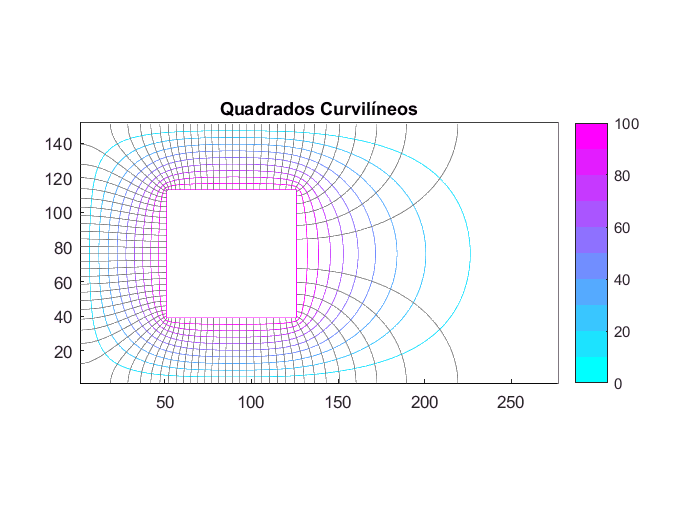

f1 = figure;
hold on;
colormap cool(10);
colorbar;
title('Quadrados Curvilíneos');

% Cria as linhas equipotenciais espaçadas em 10V
contour(V, 0:10:100);

% Cria as linhas de campo em cinza
contour(E, 0:tc:100, 'Color', [.5 .5 .5]);
axis equal;

% Desenho do condutor externo
rectangle('Position', [1 1 a_matriz b_matriz]);